# Statistical Behaviour of Cryptocurrencies

Giacomo Marciani

Department of Civil and Computer Engineering

University of Rome Tor Vergata

[gmarciani@acm.org](mailto:gmarciani@acm.org)

## `Abstract`

`This script visualizes a comparative study about the statistical behaviour of cryptocurrencies value. The dataset is provided by Cryptocompare[1], through a public REST API[2].`

`The script allows to compare an arbitrary number of cryptocurrencies, but it is initialized with the following ones:`

- `BTC: Bitcoin[3];`

- `ETH: Ethereum[4];`

- `XRP: Ripple[5];`

`This work is inteded as a final test for the course in Advanced Statistics[6,7,8].`

## `Introduction`

`First of all, let us declare the parameters for the study.`

currencies = ["BTC", "ETH"];
change = "EUR";
startDate = datetime("06-Mar-2017");
endDate = datetime("06-Mar-2018");
pace= calmonths(1);

`You can customize the study by editing the above variables ``currencies``, ``change``, ``startDate,` `endDate`` and ``pace``. Please, notice that you also have to modify accordingly the variables ``dists`` in Distribution Analysis and ``fits`` in Forecasting.`

## `Setup`

`Let us setup the required support variables:`

n = length(currencies);
data = repmat(struct('name', [], 'T', [], 'w', []), n, 1);
for i = 1:n
    data(i).name = currencies(i);
end

## `Annual Trend`

`Let us now visualize the annual trend of the currencies value.`

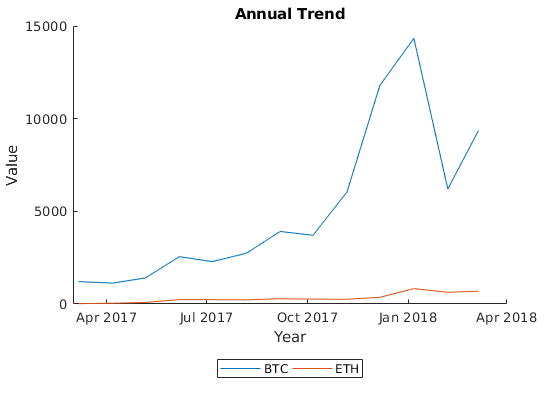

hold on

for i = 1:n
    data(i).T = fetchData(data(i).name, change, startDate, endDate, pace);
    plot(data(i).T.Date, data(i).T.Value, 'DisplayName', data(i).name);
end

hold off

title('Annual Trend');
xlabel('Year');
ylabel('Value');
legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');


figure;

## `W-Measure`

`Let us now consider the following measure`


$$w_{i}:=\frac{x_{i}-x_{i-1}}{x_{i-1}}$$


`where `$x_{i}$` is the value of the considered indicator at time `$i$`.`

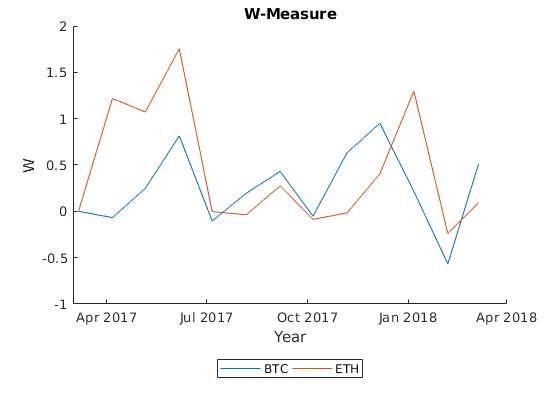

hold on

for i = 1:n
    data(i).w = getW(data(i).T.Value);
    plot(data(i).T.Date, data(i).w, 'DisplayName', data(i).name);
end

hold off

title('W-Measure');
xlabel('Year');
ylabel('W');
legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');


figure;

## `Distribution Analysis`

`Let us now study the probability distribution function of the W-measure for the indicators. Please, notice that the variable ``dists`` should be modified accordingly to the result reported by the Distribution Fitter.`

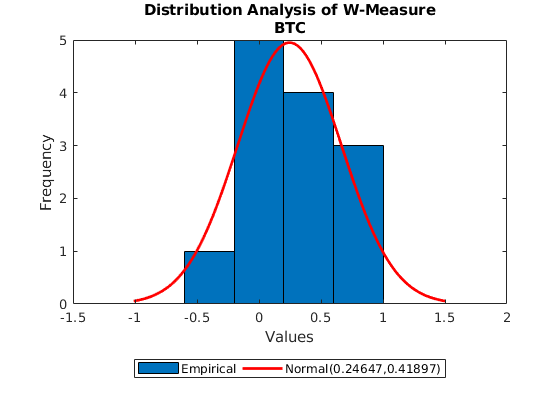

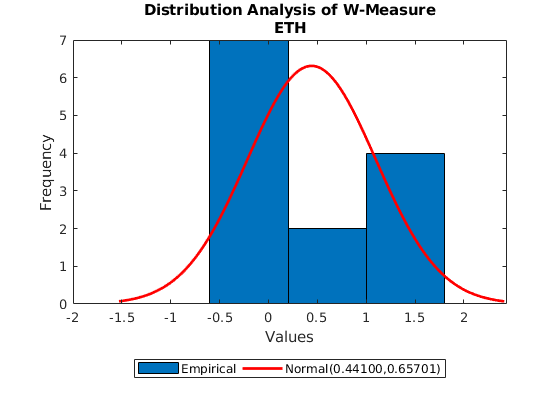

%dists = ["Normal", "Normal"];
dists = ["Normal", "Normal", "Normal"];

for i = 1:n
    bins = size(histcounts(data(i).w), 2);
    dparams = fitdist(data(i).w, char(dists(i)));

    histfit(data(i).w, bins, char(dists(i)));

    title({'Distribution Analysis of W-Measure', data(i).name});
    xlabel('Values');
    ylabel('Frequency');
    legend('Empirical', sprintf("%s(%.5f,%.5f)", dists(i), dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
    figure;
end

## `Correlation Analysis`

`Let us now consider the correlation between the indicators.`

rows = cell(nchoosek(n,2), 3);
ridx = 1;
for i = 1:n
    for j = (i+1):n
        minDate = max(data(i).T.Date(1), data(j).T.Date(1));
        maxDate = min(data(i).T.Date(end), data(j).T.Date(end));
        vlsi = data(i).T(data(i).T.Date >= minDate & data(i).T.Date <= maxDate,:).Value;
        vlsj = data(j).T(data(j).T.Date >= minDate & data(j).T.Date <= maxDate,:).Value;
        corrMatrix = corrcoef(vlsi, vlsj);
        rows(ridx,:) = {data(i).name, data(j).name, corrMatrix(1,2)};
        ridx = ridx + 1;
    end
end
disp(cell2table(rows, 'VariableNames', {'Currency1','Currency2','Correlation'}));

    Currency1    Currency2    Correlation
    _________    _________    ___________

    "BTC"        "ETH"        0.8432     



## `Forecasting`

`Let us now forecast the trend of the indicators by curve fitting. Please, notice that:`

- `fits`` should be modified accordingly to the result reported by the Curve Fitter;.`

- `futureYears`` should be modified accordignly to the desired future projection;`

- `futureSampling`` should be modified accordingly to the desired forecasting sampling;`

- `confidence`` should be modified accordingly to the desired level of confidence.`

fits = ["sin8", "sin8", "sin8"];
futureYear = 2040;
futureSampling= 2;
confidence = 0.95;

%for i = 1:n
    %mxDate = max(data(i).T.Date);
    
    %fitting = fit(data(i).T.Date, data(i).T.Value, char(fits(i)));
    
    %futureInterval = mxDate:futureSampling:futureYear;
    %futureValues = fitting(futureInterval);
    %ci = predint(fitting, futureInterval, confidence, 'observation');
    
    %plot(data(i).T.Date, data(i).T.Value, 'o');
    
    %hold on
    %plot(fitting, '--');
    %errorbar(futureInterval, futureValues, futureValues-ci(:,1), ci(:,2)-futureValues, '--');
    %hold off
    
    %title({'Forecasting', data(i).name});
    %xlabel('Year');
    %ylabel('Value');
    %legend('Empirical', 'Fitted', 'Prediction', 'Location', 'southoutside', 'Orientation', 'horizontal');
    %figure;
%end

## `KPIs`

`In the end, let us consider the some summarizing KPIs for the indicators.`

rows2 = cell(n, 7);
for i = 1:n
    [Max,Min,YMax,YMin,Mean,Std] = getKPI(data(i).T);
    rows2(i,:) = {data(i).name,Max,Min,YMax,YMin,Mean,Std};
end
disp(cell2table(rows2, 'VariableNames', {'Currency','Max','Min','YMax','YMin','Mean','Std'}));

    Currency     Max      Min         YMax           YMin         Mean      Std  
    ________    _____    ______    ___________    ___________    ______    ______

    "BTC"       14339    1127.2    06-Jan-2018    06-Apr-2017    5130.5    4266.1
    "ETH"       830.3      18.5    06-Jan-2018    06-Mar-2017    319.91    250.69



## `References`

- `Cryptocompare, `[`https://www.cryptocompare.com`](https://www.cryptocompare.com)

- `Cryptocompare API, `[`https://www.cryptocompare.com/api`](https://www.cryptocompare.com/api)

- `Bitcoin, `[`https://bitcoin.org`](https://bitcoin.org)

- `Ethereum, `[`https://www.ethereum.org`](https://www.ethereum.org)

- `Ripple, `[`https://ripple.com`](https://ripple.com)

- `Advanced Statistics, `[`http://www.massimoregoli.com/corsi/course/view.php?id=13`](http://www.massimoregoli.com/corsi/course/view.php?id=13)

- `Ross, Sheldon M. ``Introduction to probability and statistics for engineers and scientists``. Academic Press, 2014.`

- `Higham, Desmond J., and Nicholas J. Higham. ``MATLAB guide``. Vol. 150. Siam, 2016.`

## `Functions`

function T = fetchData(currency,change,startDate,endDate, pace)
% FETCHDATA Download cryptocurrency data from Cryptocompare 
% with respect to a given real currency and datetime interval.
% currency: cryptocurrency code (e.g. BTC, ETH, XRP)
% change: real currency code (e.g. EUR, USD, GBP)
% startDate: the start datetime of the historical data.
% endDate: the end datetime of the historical data.
% pace: the datetime pace for the sampling (e.g. caldays(1), calmonths(1)).
% T: the data table.
interval = startDate:pace:endDate;
rows = cell(length(interval), 2);
i = 1;
for dt = interval
    ts = posixtime(dt);
    url = sprintf('https://min-api.cryptocompare.com/data/pricehistorical?fsym=%s&tsyms=%s&ts=%d', currency, change, ts);
    rawData = webread(url);
    value = rawData.(currency).(change);
    rows(i,:) = {dt, value};
    i = i+1;
    %cell = struct2cell(rawData);
    %tblData = struct2table(rawData{2,1});
    %tblData = tblData(~cellfun(@isempty, tblData.value), :);
    %dates = cellfun(@str2num, tblData.date);
    %values = cell2mat(tblData.value);
end
T = cell2table(rows, 'VariableNames', {'Date','Value'});
T = sortrows(T, {'Date'});
end

function W = getW(X)
% WMEASURE Compute the W-measure for a vector:
% w(i)=(x(i)-x(i-1))/(x(i-1))
% X: the original vector.
% W: the vector of W-values.
n = size(X, 1);
W = zeros(n, 1);
for i = 2:n
    W(i) = (X(i)-X(i-1))/X(i-1);
end
end

function [Max,Min,YMax,YMin,Mean,Std] = getKPI(T)
% GETKPI Compute the notable values of a data table.
% T: the data table.
% Max: the maximum value in the series.
% Min: the minimum value in the series.
% YMax: the year of the maximum value of the series.
% YMin: the year of the minimum value of the series.
% Mean: the mean value of the series.
% Std: the standard deviation of the series.
yrs = T.Date;
vls = T.Value;
[Max,iMax] = max(vls);
[Min,iMin] = min(vls);
YMax = yrs(iMax);
YMin = yrs(iMin);
Mean = mean(vls);
Std = std(vls);
end